**Data**

x = [1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000]

x =     1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000


y = [3.2888    7.6111   11.9175   22.3415   35.8022   33.2350   71.6824   43.5441  90.5842   74.6333  94.7754]

y =     3.2888    7.6111   11.9175   22.3415   35.8022   33.2350   71.6824   43.5441   90.5842   74.6333   94.7754


**Plot data**

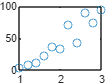

plot(x,y,'o')

**Transform data**

x = log10(x)

x =          0    0.0792    0.1461    0.2041    0.2553    0.3010    0.3424    0.3802    0.4150    0.4472    0.4771


new_y = log10(y)

new_y =     0.5170    0.8814    1.0762    1.3491    1.5539    1.5216    1.8554    1.6389    1.9571    1.8729    1.9767


**Perform linear regression & plot dataset + fitted line**

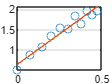

a =     2.9712    0.6496


r2 = 0.9435

[a,r2] = linregr(x,new_y)

**Computer parameters of nonlinear equation from the fitted line**

alpha = 10^a(2) %10^a0

alpha = 4.4625

beta = a(1) % a1

beta = 2.9712

**Plot the original data with the best fit nonlinear curve**

xx = 0 : 0.1 : 3

xx =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000


yy = alpha * xx.^beta

yy =          0    0.0048    0.0374    0.1247    0.2932    0.5691    0.9782    1.5465    2.2995    3.2631    4.4625    5.9233    7.6707    9.7302   12.1268   14.8858   18.0323   21.5913   25.5878   30.0468   34.9933   40.4522   46.4483   53.0064   60.1514   67.9079   76.3008   85.3548   95.0944  105.5444  116.7295


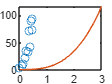

plot(x, y, 'o', xx, yy, '-')

**Predict the value of y for the given x**

xtest = 1.5

xtest = 1.5000

predict_y = alpha * xtest.^beta

predict_y = 14.8858